# Power-Split HEV for Speed Tracking - Simple Drive Pattern

## Open the Model

mdl = "PowerSplitHEV_system_model";

if not(bdIsLoaded(mdl))
  load_system(mdl);
end

% Use the speed tracking controller.
set_param(mdl+"/Controller & Environment", ...
  ReferencedSubsystem = "PowerSplitHEV_SpeedTracking_refsub");

PowerSplitHEV_params

## Load External Input Signals to Base Workspace

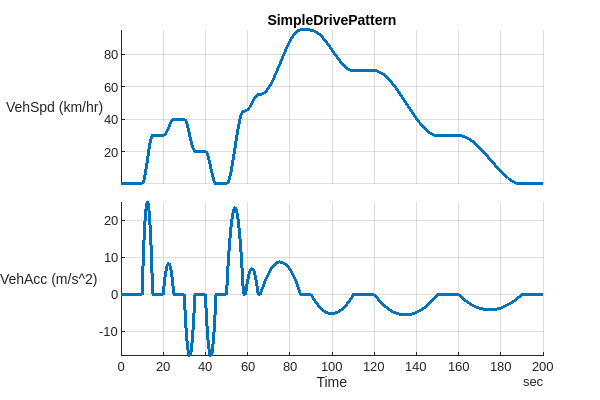

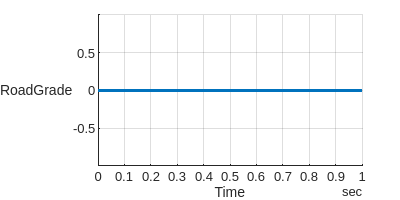

inputPattern = "SimpleDrivePattern";

% This function loads some variables in the base workspace.
PowerSplitHEV_SpeedTracking_selectInput( ...
  InputPattern = inputPattern, ...
  DisplayPlot = true );

% Simulation stop time in seconds.
t_end

t_end = 200

## Run Simulation

Set up initial conditions and block parameter values for this simulation.

% Initial SOC in the controller
initial.controllerHVBattSOC_pct = 75;

% Initial charge in the plant, which must be consistent with initial SOC
initial.highVoltageBatterySOC_pct = initial.controllerHVBattSOC_pct;
initial.hvBatteryCharge_Ahr = ...
  batteryHV.nominalCharge_Ahr * initial.hvBattery_SOC_pct/100;

initial.driverBrakeForce_N = 8000;
initial.driverBrakeOn_tf = true;

initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

Set simulation input

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, StopTime=num2str(t_end));

Run simulation

simOut = sim(simIn);

Simulated time (sec)

t_end

t_end = 200

Elapsed wall-clock time (sec)

t_elapsed = simOut.SimulationMetadata.TimingInfo.TotalElapsedWallTime

t_elapsed = 50.2052

Speed up

t_end / t_elapsed

ans = 3.9836

## Visualize Simulation Result

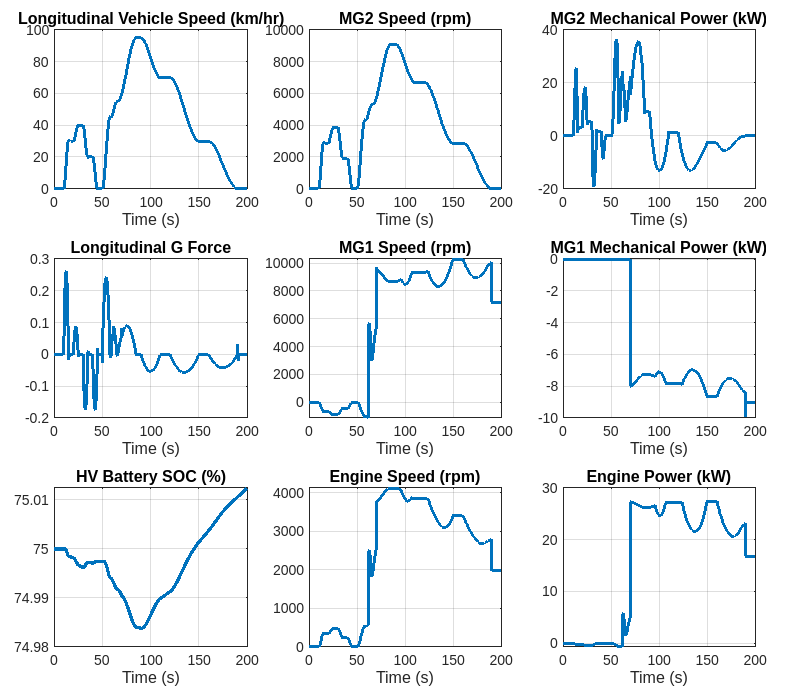

fig = figure;
PowerSplitHEV_plot_result_compact( ...
  Dataset=simOut.logsout, PlotParent=fig );

Vehicle

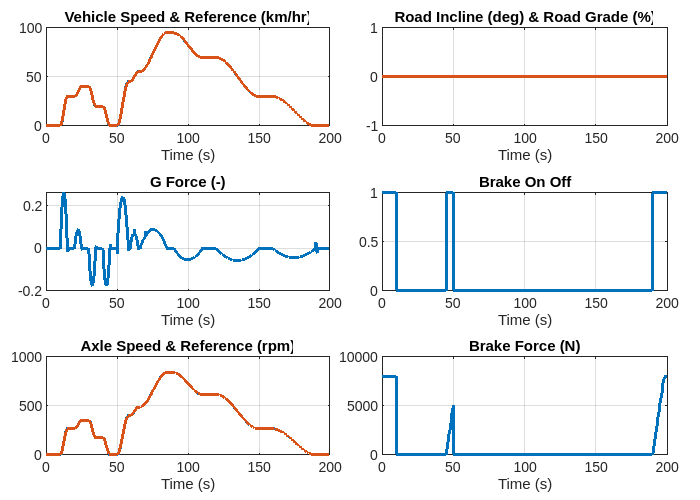

fig = figure;
PowerSplitHEV_plot_result_vehicle( ...
  Dataset=simOut.logsout, PlotParent=fig );

High Voltage Battery

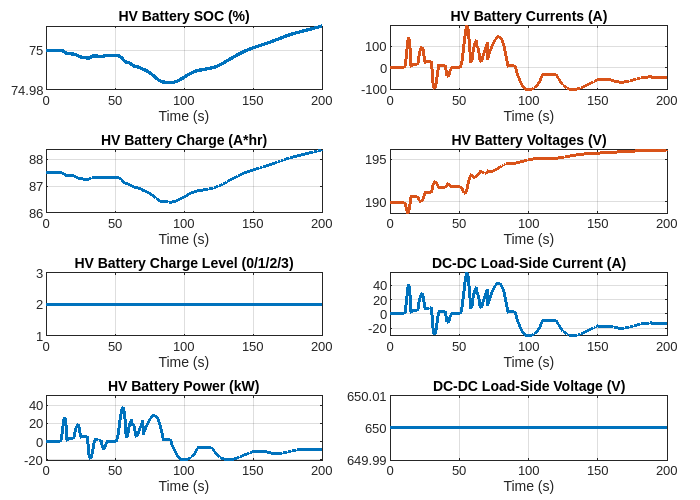

fig = figure;
PowerSplitHEV_plot_result_hvbattery( ...
  Dataset=simOut.logsout, PlotParent=fig );

Power-Split Drive Unit

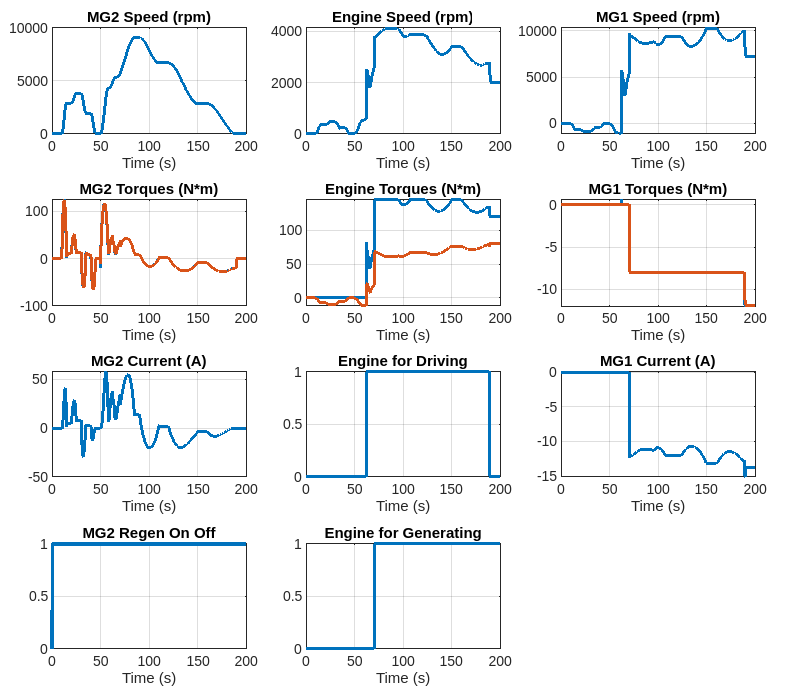

fig = figure;
PowerSplitHEV_plot_result_powersplit( ...
  Dataset=simOut.logsout, PlotParent=fig );

*Copyright 2021-2022 The MathWorks, Inc.*